# **Question 3**

clc; clear;

% define the system
s = tf('s');
G = 5*(s - 1)*(s + 1)/(2*s^4 + 14*s^3 + 36*s^2 + 44*s + 24)

G =
 
               5 s^2 - 5
  -----------------------------------
  2 s^4 + 14 s^3 + 36 s^2 + 44 s + 24
 
Continuous-time transfer function.




% extract system poles
poles = pole(G);

The appropriate sampling time would be 10 times of the most dominant pole of the system. Note that the Ts = 1/(10*fs).

% find proper sampling time
Ts = 0.1/(abs(max(real(poles))))

Ts = 0.1000

## **White Noise Input**


% define time space
t = 0:Ts:50;

% generate system input and output
N = length(t);
u = wgn(N,1,0);
y = lsim(G,u,t);

n=4;
m=3;
U = arx_U_builder(n,m,u,y);
disp("U = ")

U = 


disp(U(1:10,:))

         0         0         0         0    0.6737         0         0         0
         0         0         0         0   -0.6691    0.6737         0         0
   -0.0067         0         0         0   -0.4003   -0.6691    0.6737         0
   -0.0076   -0.0067         0         0   -0.6718   -0.4003   -0.6691    0.6737
    0.0023   -0.0076   -0.0067         0    0.5756   -0.6718   -0.4003   -0.6691
    0.0170    0.0023   -0.0076   -0.0067   -0.7781    0.5756   -0.6718   -0.4003
    0.0218    0.0170    0.0023   -0.0076   -1.0636   -0.7781    0.5756   -0.6718
    0.0241    0.0218    0.0170    0.0023    0.5530   -1.0636   -0.7781    0.5756
    0.0378    0.0241    0.0218    0.0170   -0.4234    0.5530   -1.0636   -0.7781
    0.0407    0.0378    0.0241    0.0218    0.3616   -0.4234    0.5530   -1.0636



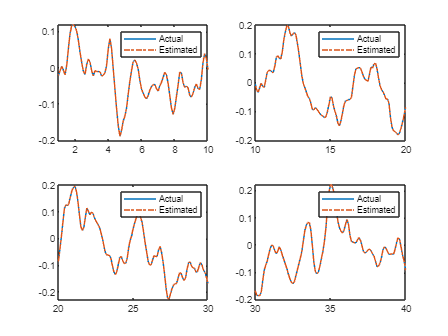

theta_hat = inv(U'*U)*U'*y;
y_hat = U*theta_hat;

figure()
subplot(2,2,1)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([1,10])

subplot(2,2,2)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([10,20])

subplot(2,2,3)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([20,30])

subplot(2,2,4)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([30,40])

%% Evaluation Metrics

disp("----------------Model Evaluation Report-------------------")

----------------Model Evaluation Report-------------------



SST = sum((y-mean(y)).^2);
SSE = sum((y-y_hat).^2);

R2 = 1 - (SSE/SST);

MSE = SSE/N;

fprintf('------> SSE : %.7f \n', SSE);

------> SSE : 0.0000011 


fprintf('------> MSE : %.7f \n', MSE);

------> MSE : 0.0000000 


fprintf('------> R2  : %.7f \n', R2);

------> R2  : 0.9999998 



disp("===========================================================")

## PRBS Input

% input & output generation
u2 = prbs(5,N);
y2 = lsim(G,u2,t);

U_prbs = arx_U_builder(n,m,u2,y2);

disp("U = ")

U = 


disp(U_prbs(1:10,:))

         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0    1.0000         0         0
   -0.0099         0         0         0         0         0    1.0000         0
   -0.0212   -0.0099         0         0    1.0000         0         0    1.0000
   -0.0234   -0.0212   -0.0099         0         0    1.0000         0         0
   -0.0303   -0.0234   -0.0212   -0.0099    1.0000         0    1.0000         0
   -0.0357   -0.0303   -0.0234   -0.0212    1.0000    1.0000         0    1.0000



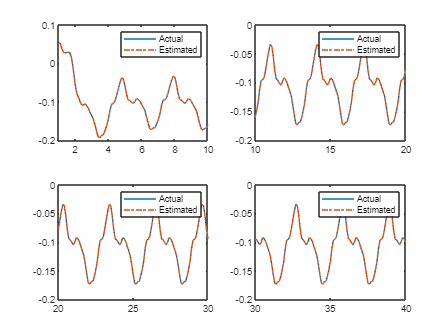


theta_hat_prbs = inv(U_prbs'*U_prbs)*U_prbs'*y2;
y_hat_prbs = U_prbs*theta_hat_prbs;



figure()
subplot(2,2,1)
plot(t,y2,t,y_hat_prbs,'-.')
legend('Actual','Estimated')
xlim([1,10])

subplot(2,2,2)
plot(t,y2,t,y_hat_prbs,'-.')
legend('Actual','Estimated')
xlim([10,20])

subplot(2,2,3)
plot(t,y2,t,y_hat_prbs,'-.')
legend('Actual','Estimated')
xlim([20,30])

subplot(2,2,4)
plot(t,y2,t,y_hat_prbs,'-.')
legend('Actual','Estimated')
xlim([30,40])

%% Evaluation Metrics

disp("----------------Model Evaluation Report-------------------")

----------------Model Evaluation Report-------------------



SST = sum((y2-mean(y2)).^2);
SSE = sum((y2-y_hat_prbs).^2);

R2 = 1 - (SSE/SST);

MSE = SSE/N;

fprintf('---(PRBS)---> SSE : %.7f \n', SSE);

---(PRBS)---> SSE : 0.0000003 


fprintf('---(PRBS)---> MSE : %.7f \n', MSE);

---(PRBS)---> MSE : 0.0000000 


fprintf('---(PRBS)---> R2  : %.7f \n', R2);

---(PRBS)---> R2  : 0.9999997 



disp("===========================================================")